Reconstructed-map corralation of modes 1:nEig

clear all
close all

addpath('/home/trangc/kg98/trangc/library/Violinplot-Matlab-master')
diagString = {'HC', 'BD', 'SCA',...
    'SCZ', 'ASD', 'MDD' };
plotOrder = [5, 2, 6, 3, 4]; %to match with plot in vbm
load('corr_MBM.mat');

nSite = length(map.numericFolders);


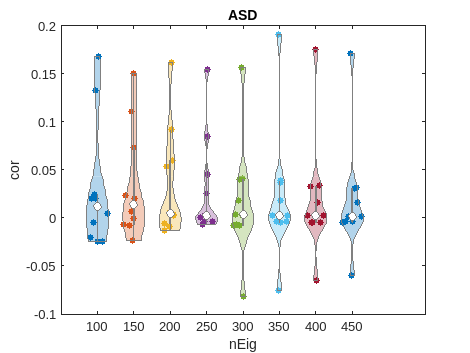

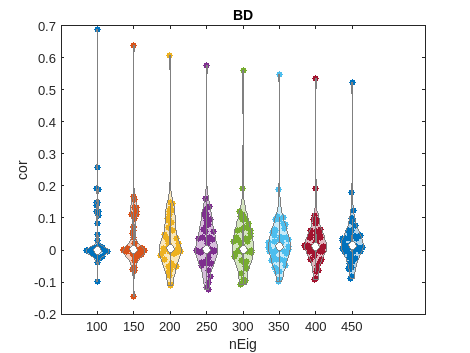

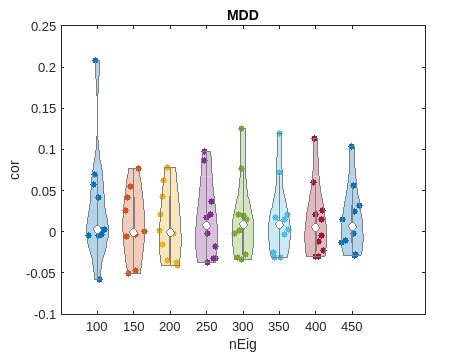

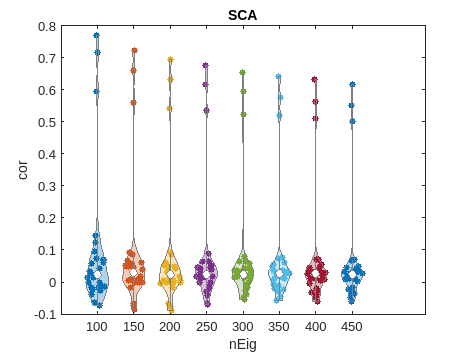

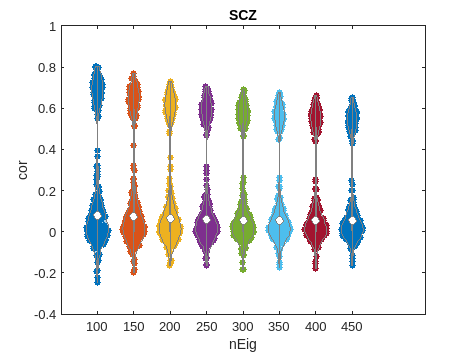


nEig = 100:50:500;

for iDiag = plotOrder
    isDiagSite = strcmp(map.diag, num2str(iDiag));
    for iNE = 1:length(nEig)-1

        map.corDiag{iDiag} =  corr((map.significantBeta(isDiagSite,1:nEig(iNE)))');
        ids=find(triu(ones(size(map.corDiag{iDiag})),1));
        corToPlot (:,iNE)= map.corDiag{iDiag}(ids);
    end
    fig = figure('Position', [200 200 800 600]);
    violinplot(corToPlot, cellfun(@num2str, num2cell(nEig), 'UniformOutput', false));
    xlabel('nEig')
    ylabel('cor')

    title(diagString(iDiag))

    xticklabels(nEig(1:length(nEig)))

    clear corToPlot

end